# Offset-free Output Tracking MPC using Innovation Bias Approach 

**Sachin C. Patwardhan*, Anjali P. Deshpande and Sharad Bhartiya* **

(*) Dept. of Chemical Engineering,

 Indian Institute of Technology Bombay, Mumbai 400076 India    

## Introduction

In the previous lesson, we have studied integration of state estimator with state space MPC formulation developed in Module 5. In this lesson we continue our journey and investigate output tracking MPC formulation. To begin with we show how to convert the output tracking MPC formulation developed using innovation bias approach to QP problem. Subsequently, we carry out simulation study using the quadruple tank system to demonstrate efficacy of the MPC formulation. 

**Learning Objectives:**

- To understand output tracking MPC formulation and it's transformation to QP problem

- To understand disturbance and MPM Rejection capabilities of output tracking MPC

## Output Tracking MPC 

This is closer to similar to the initial versions of MPC formulations used in the industrial practice. 


$$\;$$
  
$${\mathrm{U}}_p^* \left(k\right)=\overset{\arg \;\min }{{\mathrm{U}}_p \left(k\right)} \;\;J\left\lbrack y\left(k\right),\hat{x} \left(k\right),{\mathrm{U}}_p \left(k\right)\;\right\rbrack$$
   

$J\left\lbrack y\left(k\right),\hat{x} \left(k\right),{\mathrm{U}}_p \left(k\right)\;\right\rbrack ={{\left\|\hat{y} \left(k+p\right)-r_f \left(k\right)\right\|}^2 }_{W_{y,\infty } } +\sum_{j=0}^{p-1} \left\lbrace {{\left\|\hat{y} \left(k+j\right)-r_f \left(k\right)\right\|}^2 }_{W_y } \;+{{\left\|u\left(k+j|k\right)-u_s \left(k\right)\right\|}^2 }_{W_u } +{{\left\|\Delta u\left(k+j|k\right)\right\|}^2 }_{W_{\Delta u} } \right\rbrace$  ------(1)


$$\begin{array}{l}
\Delta u\left(k+j|k\right)=u\left(k+j|k\right)-\Delta u\left(k+j-1|k\right)\;\;\;\textrm{for}\;j=1,2,\ldotp \ldotp \ldotp ,p-1\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\Delta u\left(k|k\right)=\Delta u\left(k|k\right)-u\left(k-1\right)
\end{array}$$


Subject To

$\begin{array}{l}
z\left(k+j+1\right)=\Phi z\left(k+j\right)+\Gamma u\left(k+j|k\right)+L\;e_f \left(k\right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\textrm{for}\;j=0,1,2,\ldotp \ldotp \ldotp \ldotp ,p-1\;\;\textrm{and}\;\;\;z\left(k\right)=\hat{x} \left(k\right)
\end{array}$  ------(2)

$\hat{y} \left(k+j\right)=\textrm{Cz}\left(k+j\right)+e_f \left(k\right)\;\;\textrm{for}\;j=1,2,\ldotp \ldotp \ldotp \ldotp ,p\;\;$  ------(3)

${\Delta u}_L \le \Delta u\left(k+j|k\right)\le {\Delta u}_H \;\textrm{for}\;\;j=0,1,2,\ldotp \ldotp \ldotp \ldotp p-1\;$   ------(4)

     $u_L \le u\left(k+j|k\right)\le u_H$   for $j=0,1,2,\ldotp \ldotp \ldotp \ldotp p-1$ -----(5) 

Again, to keep the treatment simple, we have only retained input bound constraints. However, other constraints such as, output bounds or those arising from use of control horizon smaller than the prediction horizon, can be introduced in this formulation. Further, the cost function can be modified by including input target penalty terms. The matrix $W_{y,\infty }$ appearing on the R.H.S. of the above equation can be found by solving discrete Lyapunov equation when $\rho \left(\Phi \right)<1$

${\Phi^T W_{y,\infty } \Phi -W}_{y,\infty } ={-C}^T W_y C$ ------(6)

## Transformation of Output Tracking MPC to QP Problem 

Using the prediction model (2) and (3) repeatedly over the prediction horizon, we can write 

$\begin{array}{l}
\hat{y} \left(k+j\right)=C\left\lbrack \Phi^j \hat{x} \left(k\right)+\Phi^{j-1} \Gamma u\left(k|k\right)+\Phi^{j-2} \Gamma u\left(k+1|k\right)+\ldotp \ldotp \ldotp \ldotp \ldotp +\Gamma u\left(k+j-1|k\right)\right\rbrack \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;+C\left(\Phi^{j-1} +\Phi^{j-2} +\ldotp \ldotp \ldotp \ldotp \ldotp +I\right)\;L\;e_f \left(k\right)+e_f \left(k\right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\textrm{for}\;j=1,2,\ldotp \ldotp \ldotp \ldotp ,p\;\;
\end{array}$   -----(7)

Defining the future input vector, $U_f \left(k\right)$, and predicted output vector, $X_p \left(k\right)$, over the future horizon as

$U_f \left(k\right)={\left\lbrack {u\left(k|k\right)}^T \;{u\left(k+1|k\right)}^T \;\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp {u\left(k+p-1|k\right)}^T \right\rbrack }^T$   ------(8)

$Y_p \left(k\right)={\left\lbrack {\hat{y} \left(k+1\right)}^T \;{\hat{y} \left(k+2\right)}^T \;\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp {\hat{y} \left(k+p\right)}^T \right\rbrack }^T$-------------------(9)

the prediction model over the entire prediction horizon given by equation (8) can be expressed as a single matrix expression 

$Y_p \left(k\right)=S_x \hat{x} \left(k\right)+S_u U_f \left(k\right)+S_e \;e_f \left(k\right)$  -----(10) 

where

  
$$S_x =\left\lbrack \begin{array}{c}
C\Phi \\
C\Phi ²\\
\cdots \\
{C\Phi }^p 
\end{array}\right\rbrack \;\;\;;\;\;\;S_u =\left\lbrack \begin{array}{cccc}
C\Gamma  & \left\lbrack \begin{array}{c}
0
\end{array}\right\rbrack  & \ldotp \ldotp \ldotp \ldotp  & \left\lbrack \begin{array}{c}
0
\end{array}\right\rbrack \\
C\Phi \Gamma  & C\Gamma  &  & \\
\ldotp \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp \ldotp \\
C\Phi^{p-1} \Gamma  & C\Phi^{p-2} \Gamma  & \ldotp \ldotp \ldotp \ldotp  & C\Gamma 
\end{array}\right\rbrack \;\;\textrm{and}\;\;\;\;S_e =\left\lbrack \begin{array}{c}
\textrm{CL}+I_{r\times r} \\
C\left(\Phi +I\right)\;L+I_{r\times r} \\
\ldotp \ldotp \ldotp \ldotp \\
C\left(\Phi^{p-1} +\Phi^{p-2} +\ldotp \ldotp \ldotp +I\right)\;L+I_{r\times r} 
\end{array}\right\rbrack$$


Let us introduce a vector to represent the free response of the system as 

$Y_f \left(k\right)=S_x \hat{x} \left(k\right)+S_e \;e_f \left(k\right)$  ------(11)

and rewrite $Z_p \left(k\right)$ as follows 

$Y_p \left(k\right)=Y_f \left(k\right)+S_u U_f \left(k\right)$  -----(12)

To include the input rate penalty in the QP formulation of MPC, recall the expression that we developed by staking $\Delta u\left(k+j|k\right)$ for constraint handling in Lesson 4 (Module 5) 

$\Delta U_f \left(k\right)=\left\lbrack \begin{array}{c}
u\left(k\right)-u\left(k-1\right)\\
u\left(k+1\right)-u\left(k\right)\\
\cdots \\
u\left(k+p-1\right)-u\left(k+p-2\right)
\end{array}\right\rbrack =\Psi U_f \left(k\right)-\Psi_0 u\left(k-1\right)$ ------(13)

where

 $\Psi =\left\lbrack \begin{array}{cccc}
I & \left\lbrack \begin{array}{c}
0
\end{array}\right\rbrack  & \left\lbrack \begin{array}{c}
0
\end{array}\right\rbrack  & \left\lbrack \begin{array}{c}
0
\end{array}\right\rbrack \\
-I & I & \left\lbrack \begin{array}{c}
0
\end{array}\right\rbrack  & \left\lbrack \begin{array}{c}
0
\end{array}\right\rbrack \\
\cdots  & \cdots  & \cdots  & \left\lbrack \begin{array}{c}
0
\end{array}\right\rbrack \\
\left\lbrack \begin{array}{c}
0
\end{array}\right\rbrack  & \cdots  & -I & I
\end{array}\right\rbrack$   and $\Psi_0 =\left\lbrack \begin{array}{c}
I\\
\left\lbrack \begin{array}{c}
0
\end{array}\right\rbrack \\
\cdots \\
\left\lbrack \begin{array}{c}
0
\end{array}\right\rbrack 
\end{array}\right\rbrack$   ------(14)

Defining stacked target vectors 

$\;\;R_f \left(k\right)=\left\lbrack \begin{array}{c}
r_f \left(k\right)\\
\ldotp \ldotp \ldotp \ldotp \\
r_f \left(k\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
I_{r\times r} \\
\ldotp \ldotp \ldotp \ldotp \\
I_{r\times r} 
\end{array}\right\rbrack ={\mathbf{I}}_R r_f \left(k\right)\;\;\;$ ----------(15)

the cost function (1) can be expressed as 

$J={\left(Y_p \left(k\right)-R_f \left(k\right)\right)}^T {\mathbf{W}}_Y \left(Y_p \left(k\right)-R_f \left(k\right)\right)+{\left(U_f \left(k\right)-U_s \left(k\right)\right)}^T {\mathbf{W}}_U \left(U_f \left(k\right)-U_s \left(k\right)\right)+{\left(\Delta U_f \left(k\right)\right)}^T \;\;{\mathbf{W}}_{\Delta U} \;\Delta U_f \left(k\right)$ -----(16)

where 


$${\mathbf{W}}_Y =\left\lbrack \begin{array}{cccc}
W_y  & \left\lbrack \begin{array}{c}
0
\end{array}\right\rbrack  & \ldotp \ldotp \ldotp  & \left\lbrack 0\right\rbrack \\
\left\lbrack 0\right\rbrack  & W_y  & \ldotp \ldotp \ldotp  & \left\lbrack 0\right\rbrack \\
 &  & \ddots  & \\
\left\lbrack 0\right\rbrack  & \left\lbrack 0\right\rbrack  & \ldotp \ldotp \ldotp  & W_y 
\end{array}\right\rbrack$$


where ${\mathbf{W}}_Y$ and ${\mathbf{W}}_U$ are block diagonal weighting matrices as defined in Lesson 2 of Module 5. Now consider expansion of the first term in the R.H.S. of (34), i.e. 

${\left(Y_p \left(k\right)-R_f \left(k\right)\right)}^T {\mathbf{W}}_Y \left(Z_p \left(k\right)-R_f \left(k\right)\right)={\left(S_u U_f \left(k\right)+\left(Y_f \left(k\right)-R_f \left(k\right)\right)\right)}^T {\mathbf{W}}_Y \left(S_u U_f \left(k\right)+\left(Y_f \left(k\right)-R_f \left(k\right)\right)\right)$  ------(17)

From the viewpoint of optimization terms ${\left(Y_p \left(k\right)-R_f \left(k\right)\right)}^T {\mathbf{W}}_Y \left(Z_p \left(k\right)-R_f \left(k\right)\right)$ can be ignored and only quadratic and linear terms in $U_f \left(k\right)$ need to be retained. With some algebraic manipulations of the remaining two terms (ref Lesson 4 in Module 5), the QP cost function can be reduced to  

$J\;=\frac{1}{2}{{\;U}_f \left(k\right)}^T \;\mathbf{H}\;U_f \left(k\right)+{F\left(k\right)}^T U_f \left(k\right)$  -----(18a) 

$\begin{array}{l}
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\mathbf{H}=2\left({S_u }^T {\mathbf{W}}_Y S_u +{\mathbf{W}}_U +\Psi^T {\mathbf{W}}_{\Delta U} \Psi \right)\;\\
F\left(k\right)={2\left(S_u \right)}^T {\mathbf{W}}_Y \;\left(Y_f \left(k\right)-R_f \left(k\right)\right)\;-2\left(\Psi^T \;{\mathbf{W}}_{\Delta U} \Psi_0 \right)u\left(k-1\right)-2\;\left({\mathbf{W}}_U {\mathbf{I}}_U \right)u_s 
\end{array}$ ------(18b)

##  Quadruple Tank System: Disturbance and MPM Rejection

In this section, we repeat the simulation exercise carried out in the previous lesson using the output tracking MPC. 

 
clear all 
close all

global QTank U_k D_k

Set_Graphics_Parameters ;   % This script file sets font size and line thickness for figures 

**Task 1**: Select the operating point for Q Tank process.  This will load quadruple tank parameters and steady state corresponding to the chosen operating point. Users can see the QTank data structure in workspace.

operating_pt=2;

% Load quadruple tank parameters and steady state 
% The following file loads QTank data structure 
if operating_pt==1
load QTank_MinPhase_Model
else
 load QTank_NonMinPhase_Model 
end


**Task 2**: Set the simulation run time N = 500 to study only the disturbance rejection and N = 1000 to additionally see servo response. 

N = 1200 ;      % Simulation run time

**Matrices for process simulation **

% Quadruple tank System Linear Discrete Time Model matrices
phy= QTank.phy ;  
gam = QTank.gama_u ;
gam_d = QTank.gama_d ; 
C_mat = [1 0 0 0 ; 0 1 0 0]  ; % Levels h(1) and h(2) are measured in quadruple tank 
[n_op, nx ] = size(C_mat)  ;
[n_st, n_ip] = size(gam) ;
[nx, n_d] = size(gam_d) ;

**Initialize internal model for MPC**

mpc.phy= phy ;  
mpc.gam = gam ;
mpc.gam_d = gam_d ; 
mpc.C_mat = C_mat ;
mpc.n_st = n_st ; mpc.n_op = n_op ;  mpc.n_ip = n_ip ; 

u_H = [5 5]' - QTank.Us ;  % Physical Input bounds low are 0 and 5 Volts 
u_L = [0 0]' - QTank.Us ;  % Steady state inputs are [3 3] 

QT_sys = ss(phy, [gam gam_d], C_mat, zeros(n_op,n_ip+n_d), QTank.samp_T ) ;
Q_mat = 0.0025 ;
R_mat = QTank.R_mat ;

**MPC Tuning Parameters**

**Task 3: **Set the prediction horizon n_pred to interval >= 50**. Note: **Control horizon is set equal to prediction horizon 

mpc.n_pred =50; 

**Task 4:** We have created variables ${\textrm{mpc}\ldotp W}_u$, the **Input Weighting Matrix,** ${\textrm{mpc}\ldotp W}_{\textrm{delu}}$, the **Input Rating Weighting Matrix **and . Set them as identity matrices. [One can use eye command in MATLAB](https://in.mathworks.com/help/matlab/ref/eye.html) or form the matrices as shown below.

 $W_y =\left\lbrack \begin{array}{cc}
\alpha_1  & 0\\
0 & \alpha_2 
\end{array}\right\rbrack$,  $W_u =\left\lbrack \begin{array}{cc}
\beta_1  & 0\\
0 & \beta_2 
\end{array}\right\rbrack$ and  $W_{\Delta u} =\left\lbrack \begin{array}{cc}
\gamma_1  & 0\\
0 & \gamma_2 
\end{array}\right\rbrack$

beta(1)=1;
beta(2)=1;
disp('Input weighting matrix')

Input weighting matrix


mpc.Wu = diag(beta);
gamma(1)=10000;
gamma(2)=10000;
disp('Input Rate weighting matrix')

Input Rate weighting matrix


mpc.Wdelu = diag(gamma) ;% Input Rate weighting matrix. Note: Effect is seen only if large weighting is used 
alpha(1)=22;
alpha(2)=15;
disp('Output weighting matrix')

Output weighting matrix


mpc.Wy = diag(alpha);  % Output weighting matrix
mpc.u_H = [5 5]' - QTank.Us ;  % Physical Input bounds low are 0 and 5 Volts 
mpc.u_L = [0 0]' - QTank.Us ;  
% mpc.deluL = [] ; mpc.deluH = [] ; 
mpc.deluH = [0.025 0.025]';  % Specify input rate constraints.
mpc.deluL = -mpc.deluH ;

mpc.xs_k = zeros(mpc.n_st,N);
mpc.us_k = zeros(n_ip,N) ;
mpc.xkhat = zeros(mpc.n_st,N);
mpc.yhatk = zeros(n_op,N) ;

% Kalman predictor design 

 [KEST,L_inf,P_inf] = kalman(QT_sys, Q_mat, R_mat, zeros(n_d,n_op),'delayed')  ;
 rho_obs = max(abs(eig(phy - L_inf * C_mat )))

rho_obs = 0.9423

We have set **CL_Observer_ON** flag to **No** so that MPC controller reduces to vanilla MPC based on the model as open loop observer. 

CL_Observer_ON=1;% Set this value to zero to simulate open loop observer based vanilla MPC 
 mpc.L_mat =  CL_Observer_ON * L_inf ;

**Generation of  QP matrices**

[ mpc] = Gen_QP_Matrices_OP_Tracking_delU(mpc) ;

**Task 5: **Change disturbance filter parameter between 0.9 and 0.99. Setting it equal to zero will eliminate innovation filter. 

alfa_e=0.979;
mpc.phy_d = alfa_e * eye(n_op) ;   % Disturbance filter matrix 
mpc.dkhat = zeros(n_op,N); % Model plant mismatch signal 
mpc.dkhat_f = zeros(n_op,N); % Filtered Model plant mismatch signal

**Task 6: **Change setpoint filter parameter between 0.9 and 0.99. Setting it equal to zero will eliminate innovation filter. 

rk_f = zeros(n_op,N);  
beta_r=0.979;
phy_r = beta_r * eye(n_op) ; % Setpoint filter matrix 

**Process simulation related matrices are initialized here. **

% Matrices for simulating system dynamics 
xk = zeros(n_st,N);
xk(:,1) = [-1 1 -1 1]';   % Initial state is away from the origin
uk = zeros(n_ip,N) ;
yk = zeros(n_op,N);
yk(:,1) = C_mat * xk(:,1) ; 
dk = zeros(1,N) ;
rk = [0 0]';
gam_d=QTank.gama_d;

**Task 7: **Set the value of **Noise_ON** flag to 1 to introduce white noise disturbances.  We then generate state and measurement noise sequences

Noise_ON =1

Noise_ON = 1

% Generate state and measurement noise sequences 
 % Set this value to 1 to introduce white noise disturbances  
wk = mvnrnd(zeros(n_d,1), Q_mat, N) ;
wk = Noise_ON * wk' ;
vk = mvnrnd(zeros(n_op,1), R_mat, N) ;
vk = Noise_ON * vk' ;

% Disturbance input 
for k = 1:N
    if ( k < 250 )
        dk(k) = 0 ;
    elseif (k >= 250 ) && (k < 500)
        dk(k) = 0.5 ;  % Introduce disturbance change at k = 250
    else
        dk(k) = 0.25 ;  % Introduce another disturbance change at k = 500
    end
end
dk = dk + [zeros(1, 250) wk(251:end) ] ; 

**Closed loop simulation with MPC QP **

state_est_err = zeros(n_st,N) ;

**Task 8: **Select the plant simulation as nonlinear, to add plant model mismatch in the simulations

% Closed loop simulations using QP-LMPC under model-plant mismatch 
Plant_Sim =0  ; 

for k = 1:N-1
    % Controller calculations at instant k assuming state vector is perfectly measured 
    kT(k) = (k-1) ;

    if ( k > 750 ), rk = [1 -1]';  end   % Introduce setpoint change at 750 
    rk_f(:,k+1) = phy_r * rk_f(:,k) + (eye(n_op) - phy_r) * rk   ; 

     % MPC implementation at instant k
    [mpc, u_k ] = MPCQP_OutputTracking( mpc, yk(:,k), rk_f(:,k+1), k ) ;
     mpc.uk = u_k ;
  
    % Quadruple tank Plant Simulation from k to k+1

    if (Plant_Sim )
        uk(:,k) = mpc.uk ;
        xk(:,k+1) = phy * xk(:,k) + gam * uk(:,k) + gam_d * dk(k)  ;
    else
        uk(:,k) = mpc.uk ;
        U_k = QTank.Us + mpc.uk ;
        D_k =  QTank.Ds + dk(k)  ;
        [T,Xt] = ode45( 'QTank_Dynamics' , [ 0 QTank.samp_T ], QTank.Xs+xk(:,k)) ;   % Nonlinear plant simulation
        xk(:,k+1) = Xt( end,: )' - QTank.Xs ;
    end
    yk(:,k+1) = C_mat * xk(:,k+1) + vk(:,k+1);  %Measurement with noise

 end
uk(:,N) = uk(:,N-1) ;
kT(N) = N-1 ;
mpc.dkhat(:,N) = mpc.dkhat(:,N-1) ; 
mpc.us_k(:,N) = mpc.us_k(:,N-1) ;
mpc.xs_k(:,N) = mpc.xs_k(:,N-1) ;


**Function for MPC QP formulation**

% <--------------MPC QP function---------------
% Inputs: Measurement and setpoint at instant k 
% Output: Manipulated input at instant k 

function [mpc, u_k ]  = MPCQP_OutputTracking(mpc, y_k, r_k, k) 

  % Estimate model plant mismatch and filter it using unity gain filter 
    mpc.yhatk(:,k) = mpc.C_mat * mpc.xkhat(:,k) ; 
    mpc.dkhat(:,k) = y_k - mpc.yhatk(:,k) ;
  mpc.dkhat_f(:,k+1) = mpc.phy_d * mpc.dkhat_f(:,k) + (eye(mpc.n_op) - mpc.phy_d) * mpc.dkhat(:,k) ;
 

    % Target state computation using quadratic programming 
    options=optimoptions('quadprog', 'display', 'off');
    Fsk_vec = mpc.Fs_mat * ( r_k - mpc.Gain_e *  mpc.dkhat_f(:,k))  ; 
    [us_k_QP, fsval] = quadprog(mpc.Hs_mat, Fsk_vec,mpc.As_mat, mpc.bs_vec, [],[],[],[],[], options )  ;
    mpc.us_k(:,k) = us_k_QP ; 
    mpc.xs_k(:,k) = inv(eye(mpc.n_st) - mpc.phy) * ( mpc.gam * mpc.us_k(:,k) + mpc.L_mat *  mpc.dkhat_f(:,k))  ;

    % MPC QP controller implementation 

     if (isempty(mpc.deluL)==0 )
        if (k > 2 )
            % b_vec = mpc.F_vec+mpc.B_mat*uk(:,k-1);
            % Note before QP calculations, mpc.uk = uk(:,k-1)
            b_vec = mpc.F_vec+mpc.B_mat* mpc.uk;
        else
            b_vec = mpc.F_vec +mpc.B_mat*zeros(mpc.n_ip,1) ;
        end
    else
        b_vec = mpc.F_vec ;
     end

    if ( k == 1)
        Fk_vec = mpc.F_mat*mpc.xkhat(:,k) ;
    else
        % Fk_vec = mpc.F_mat*mpc.xkhat(:,k) - 2 * mpc.psi_mat' * mpc.WdelU_mat * mpc.psi_0_mat * uk(:,k-1) ;
        % Note before QP calculations, mpc.uk = uk(:,k-1)
        Fk_vec = mpc.F_mat*mpc.xkhat(:,k) - 2 * mpc.psi_mat' * mpc.WdelU_mat * mpc.psi_0_mat * mpc.uk ;
    end
    Fk_vec = Fk_vec + 2 * mpc.Su_mat' * mpc.WY_mat * mpc.Se_mat * mpc.dkhat_f(:,k)...
             - 2 * mpc.WU_mat * mpc.Iu_mat * mpc.us_k(:,k)  - 2 * mpc.Su_mat' * mpc.WY_mat * mpc.Ir_mat * r_k ;

    [Uf_k,FVAL] = quadprog(mpc.H_mat, Fk_vec, mpc.A_mat, b_vec,[],[],[],[],[],options)  ;
    u_k = Uf_k(1:mpc.n_ip) ;  % Implement only optimal u(k) 

    % Internal MPC model update from k to k+1
     mpc.xkhat(:,k+1) = mpc.phy * mpc.xkhat(:,k) + mpc.gam * u_k + mpc.L_mat * mpc.dkhat(:,k) ;
end 

**Display Simulation Results **

Xk = QTank.Xs + xk ;   Uk = QTank.Us + uk ; Dk = QTank.Ds + dk ;
Yk = yk + C_mat * QTank.Xs ;  Rk_f = rk_f + C_mat * QTank.Xs ;
u_limit = [mpc.u_L(1)*ones(N,1) mpc.u_H(1)*ones(N,1)]  ;

** Controlled output profiles **

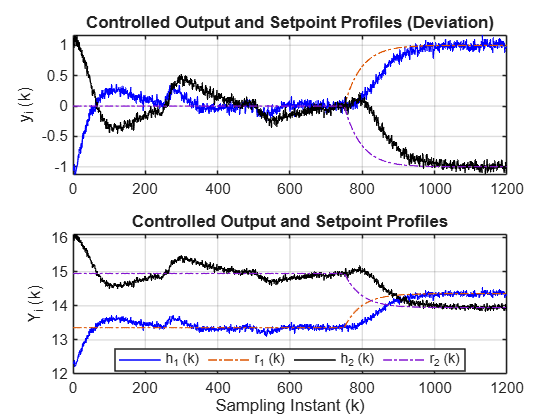

figure, subplot(211), 
plot(kT, yk(1,:), 'b',  kT, rk_f(1,:), '-.', kT, yk(2,:), 'k', kT, rk_f(2,:), '-.'), grid
title('Controlled Output and Setpoint Profiles (Deviation)'), ylabel('y_i (k)')
subplot(212), plot(kT, Yk(1,:), 'b',  kT, Rk_f(1,:), '-.', kT, Yk(2,:), 'k', kT, Rk_f(2,:), '-.'), grid
xlabel('Sampling Instant (k)'), ylabel('Y_i (k)')
legend('h_1 (k)', 'r_1 (k)', 'h_2 (k)', 'r_2 (k)', 'Orientation','horizontal','Location','Best')
title('Controlled Output and Setpoint Profiles')

**Manipulated input profiles**

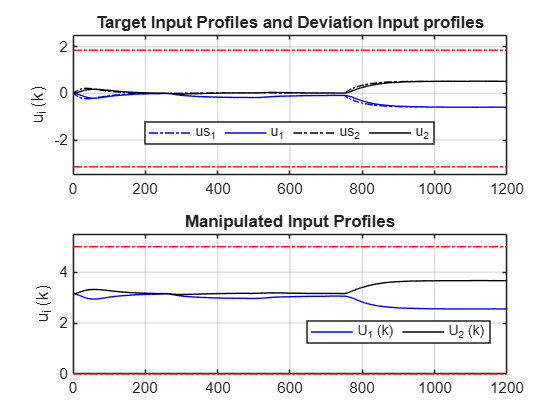

figure, subplot(211), stairs(kT, mpc.us_k(1,:)', '-.b','LineWidth',1), grid
hold on
stairs(kT, uk(1,:)', 'b','LineWidth',1)
stairs(kT, mpc.us_k(2,:)', '-.k','LineWidth',1)
stairs(kT, uk(2,:)', 'k','LineWidth',1)
stairs(u_limit, '-.r', 'LineWidth',1)
axis([0 N -3.5 2.5])
hold off
ylabel('u_i (k)'), title('Target Input Profiles and Deviation Input profiles')
legend( 'us_1', 'u_1', 'us_2', 'u_2', 'Orientation','horizontal','Location','Best')
subplot(212), stairs(kT, Uk(1,:)', 'b','LineWidth',1),  grid
hold on, stairs(kT, Uk(2,:)', 'k','LineWidth',1),
stairs(u_limit+QTank.Us', '-.r', 'LineWidth',1), hold off
axis([0 N 0 5.5]), ylabel('u_i (k)')
title('Manipulated Input Profiles')
legend( 'U_1 (k)', 'U_2 (k)','Orientation','horizontal','Location','Best')

**Disturbance input and Model Plant Mismatch profiles **

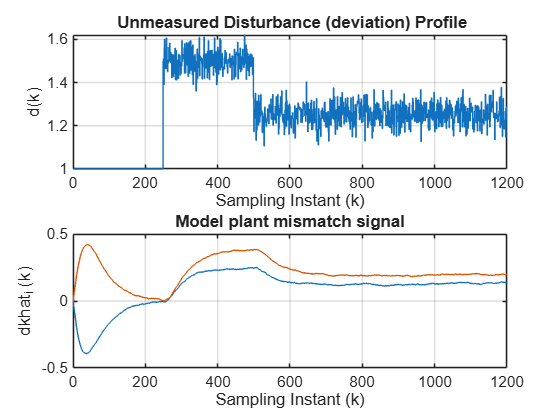

figure, subplot(211), stairs( kT, Dk,'LineWidth',1 ), grid
xlabel('Sampling Instant (k)'), ylabel('d(k)')
title(' Unmeasured Disturbance (deviation) Profile')
subplot(212), stairs( kT, mpc.dkhat_f','LineWidth',1 ), grid
xlabel('Sampling Instant (k)'), ylabel('dkhat_i (k)')
title('Model plant mismatch signal')

**System State profiles and MPC internal model profiles  **

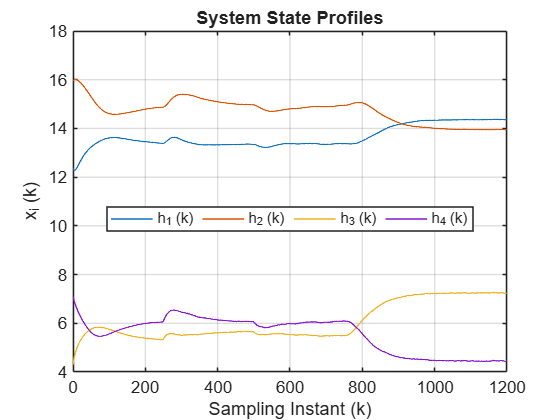

figure, plot(kT, Xk(1,:), kT, Xk(2,:), kT, Xk(3,:), kT, Xk(4,:)), grid
xlabel('Sampling Instant (k)'), ylabel('x_i (k)')
legend('h_1 (k)', 'h_2 (k)', 'h_3 (k)', 'h_4 (k)', 'Orientation','horizontal','Location','Best')
title('System State Profiles')

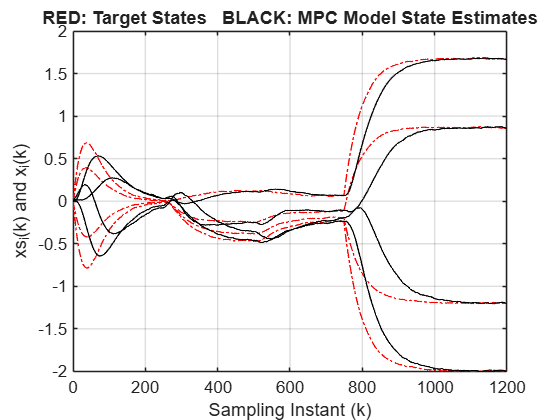

figure, plot(kT, mpc.xs_k, '-.r', kT, mpc.xkhat, 'k'), grid
title('RED: Target States   BLACK: MPC Model State Estimates')
xlabel('Sampling Instant (k)'), ylabel('xs_i(k) and x_i(k)')

Observe the results of simulation. 

**Task 9: **Observe the results by increasing or decreasing the output weighting matrix. What happens if the two values are not identical?

**Task 10:** You can change the operating point and repeat the exercise. 

## Conclusions

In this lesson we have developed an output tracking MPC formulation, which is very similar to initial MPC variants that appeared in the process industry. The performances of state space MPC presented in the previous lesson and output tracking MPC are qualitatively similar. 